# **TO- Snow Emission Model**

## Forward Simulation

clear; clc;
Tcanopy =   265;        % Temperature of the canopy [K]
tau = 0.1;              % Vegetation Optical Depth (VOD)
omega = 0.07;           % Single scattering vegetation albedo
h = 0.15;               % Roughness parameter (Q/H roughness)
freq= 1.4;              % Frequency at L-band [GHz]
obs_angle = 40;         % Observation angle
Tsoil = 265;            % Temperature of soil
rho_s = 250;            % Density of snowpack
epsr_ground = 5 -0.5i;  % Dielectric constant of ground

Tb= TO_snow(Tcanopy,tau,omega,h,freq,obs_angle,Tsoil,rho_s,epsr_ground);


## Sensitivity Analysis

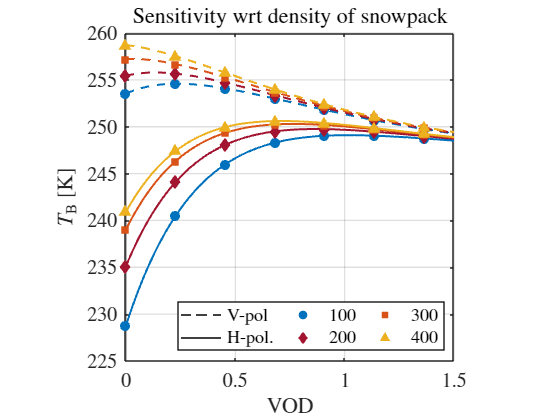

clear; clc;

Tcanopy =   265;
omega = 0.07;
h = 0.3;
freq= 1.4;
obs_angle = 40;
Tsoil = 270;
density = [100,200,300,400];
tau = linspace(0,1.5,100);
epsr_ground = 5 -0.5i;

for i = 1: length(density)
    for j = 1: length(tau)
        Tb1(:,j,i) = TO_snow(Tcanopy,tau(j),omega,h,freq,obs_angle,Tsoil,density(i),epsr_ground);
    end
end


% Plot Figure
figure;
color = [0 0.4470 0.7410; 0.6350 0.0780 0.1840; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250];
marker = {'o', 'diamond', 'square','^'};
linewidth=1.5;
for i = 1: length(density)
ph = plot(tau,Tb1(2,:,i),...
    LineStyle='none', Color=color(i,:)); hold on;
ph(1).LineStyle='--'; ph(1).LineWidth=linewidth;
ph(1).Marker=marker(i); ph(1).MarkerIndices=1:15:length(tau); ph(1).MarkerFaceColor=color(i,:);
end
hold on
for i = 1: length(density)
ph = plot(tau,Tb1(1,:,i),...
     Color=color(i,:),LineStyle = 'none'); hold on;
ph(1).LineStyle='-'; ph(1).LineWidth=linewidth;
ph(1).Marker=marker(i); ph(1).MarkerIndices=1:15:length(tau); ph(1).MarkerFaceColor=color(i,:);
end
title('Sensitivity wrt density of snowpack','FontSize',15,'Interpreter','latex')
xlabel('VOD','FontSize',15,'Interpreter','latex')
ylabel('$T_{\rm B}$ [K]','FontSize',15,'Interpreter','latex')
set(gca,'Fontsize',15,'TickLabelInterpreter','latex','LineWidth',1)
axis("square"); 
grid on;
ax2(1) = plot(nan,nan,'--',Color = 'k');
ax2(2) = plot(nan,nan,'-',Color = 'k');
for i = 1: length(density)
ax1(i) = scatter(nan(1,3),nan(1,3),MarkerEdgeColor = color(i,:),Marker = marker(i),MarkerFaceColor=color(i,:)); hold on;
end 
legend([ax2,ax1],{'V-pol','H-pol.','100','200','300','400'},...
    "Interpreter","latex","Location","southeast",Orientation="vertical",NumColumns=3);
set(gca,'Fontsize',15,'TickLabelInterpreter','latex','LineWidth',1)
axis("square")